**Integrals**

Numerical Area under a curve

- cummulative sum --> cumsum( )

- takes in  a vector of y values and gives back the area under the curve using rectangular Reman sums

- assumes width of each rectangle is 1, thus area is given by y (height)

- cumulative trapazoidal sum --> cumtrapz( )

- takes in  a vector of y values and gives back the area under the curve using trapazoidal approximation

- takes in x and y because it does not assume even spacing by 1. 

- uses area of trapezoids to approx area under curve

- trapazoidal sum --> trapz( )

- returns total area under a curve using trapezoidal approximation

- (ie, the last number in the vector returned by cumtrapz)

- Analytical Integral (power rule)

- 2*x^2 + 4*x + 5 ---> 2/3*x^3 + 4/2*x^2 + 5*x + C

- coefficients = [2 4 5]

- powers = [2 1 0]

- intPowers = powers + 1 = [3 2 1]

- intCoefficients = coefficients ./ intPowers = [2 4 5] ./ [3 2 1] = [2/3 4/2 5]

- Must increase by a constant C to increase order by one --> [2/3 4/2 5 C]

- We assume C = 0 unless told otherwise --> [2/3 4/2 5 0]

cumsum()

vec = [1 2 3 4 5]

vec =      1     2     3     4     5


svec = cumsum(vec)

svec =      1     3     6    10    15


cumtrapz()

vec = [1 2 3 4 5]

vec =      1     2     3     4     5


svec = cumtrapz(vec)

svec =          0    1.5000    4.0000    7.5000   12.0000


trapz()

vec = [1 2 3 4 5]

vec =      1     2     3     4     5


svec = trapz(vec)

svec = 12

First Order Function

disp('Integral of First Order Function')

Integral of First Order Function



figure
hold on
grid on

x = -5:5;
y = 2*x + 3;  
plot(x,y,'r','linewidth',2) 

%Numerical Integrals
inty = cumsum(y)

inty =     -7   -12   -15   -16   -15   -12    -7     0     9    20    33


plot(x, inty, 'g','linewidth',2)

inty = cumtrapz(y)

inty =      0    -6   -10   -12   -12   -10    -6     0     8    18    30


plot(x, inty, 'c','linewidth',2)

%Analytical Integral (Power Rule)
coeffs = [2 3]

coeffs =      2     3


pow = length(coeffs)-1 : -1 : 0

pow =      1     0


intPow = pow + 1

intPow =      2     1


intCoeffs = coeffs ./ intPow

intCoeffs =      1     3


intCoeffs(end+1) = 0

intCoeffs =      1     3     0


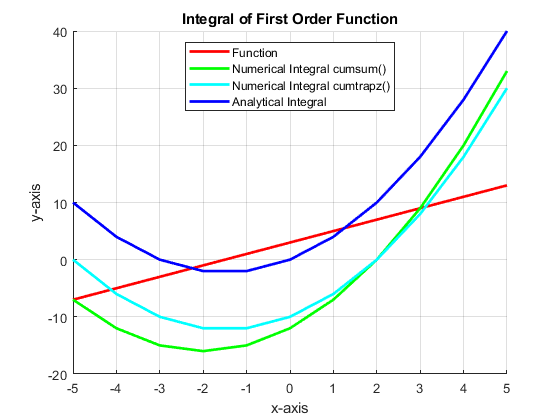

inty = polyval(intCoeffs, x);
plot(x,inty,'b','linewidth',2)

%Annotaions
title('Integral of First Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Integral cumsum()', 'Numerical Integral cumtrapz()' , 'Analytical Integral', 'location','north')

Second Order Function

disp('Integral of Second Order Function')

Integral of Second Order Function



figure
hold on
grid on

x = -5:5;
y = 2*x.^2 + 5*x + 3;  
plot(x,y,'r','linewidth',2) 

%Numerical Integrals
inty = cumsum(y)

inty =     28    43    49    50    50    53    63    84   120   175   253


plot(x, inty, 'g','linewidth',2)

inty = cumtrapz(y)

inty =          0   21.5000   32.0000   35.5000   36.0000   37.5000   44.0000   59.5000   88.0000  133.5000  200.0000


plot(x, inty, 'c','linewidth',2)

%Analytical Integral (Power Rule)
coeffs = [2 5 3]

coeffs =      2     5     3


pow = length(coeffs)-1 : -1 : 0

pow =      2     1     0


intPow = pow + 1

intPow =      3     2     1


intCoeffs = coeffs ./ intPow

intCoeffs =     0.6667    2.5000    3.0000


intCoeffs(end+1) = 0

intCoeffs =     0.6667    2.5000    3.0000         0


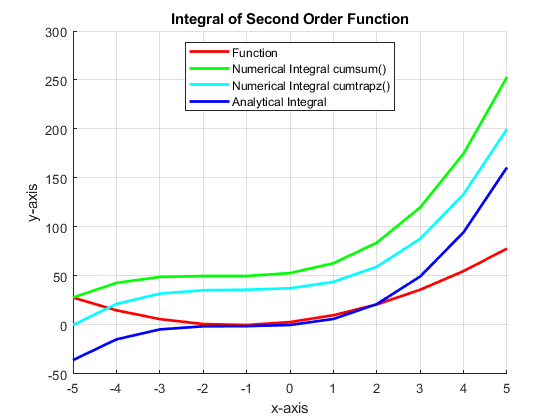

inty = polyval(intCoeffs, x);
plot(x,inty,'b','linewidth',2)

%Annotaions
title('Integral of Second Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Integral cumsum()', 'Numerical Integral cumtrapz()' , 'Analytical Integral', 'location','north')

Third Order Function

disp('Integral of Third Order Function')

Integral of Third Order Function



figure
hold on
grid on

x = -5:5;
y = 2*x.^3 + 5*x.^2 + 3*x + 8;  
plot(x,y,'r','linewidth',2) 

%Numerical Integrals
inty = cumsum(y)

inty =   -132  -184  -194  -188  -180  -172  -154  -104    12   240   638


plot(x, inty, 'g','linewidth',2)

inty = cumtrapz(y)

inty =      0   -92  -123  -125  -118  -110   -97   -63    20   192   505


plot(x, inty, 'c','linewidth',2)

%Analytical Integral (Power Rule)
coeffs = [2 5 3 8]

coeffs =      2     5     3     8


pow = length(coeffs)-1 : -1 : 0

pow =      3     2     1     0


intPow = pow + 1

intPow =      4     3     2     1


intCoeffs = coeffs ./ intPow

intCoeffs =     0.5000    1.6667    1.5000    8.0000


intCoeffs(end+1) = 0

intCoeffs =     0.5000    1.6667    1.5000    8.0000         0


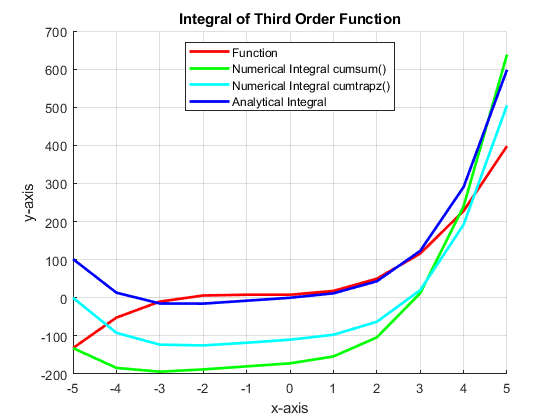

inty = polyval(intCoeffs, x);
plot(x,inty,'b','linewidth',2)

%Annotaions
title('Integral of Third Order Function')
xlabel('x-axis')
ylabel('y-axis')
legend('Function','Numerical Integral cumsum()', 'Numerical Integral cumtrapz()' , 'Analytical Integral', 'location','north')